# Project Team 12 - Data Analysis - Data Driven Marketing

## PROCESSING DATA

### **Loading Data**

% import file marketingdata
marketingdata = importfile('marketingdata.csv', 2, 2241);
% import file marketingdata theo column
[ID,Year_Birth,Education,Marital_Status,Income,Kidhome,Teenhome,Dt_Customer,Recency,MntWines,MntFruits,MntMeatProducts,MntFishProducts,MntSweetProducts,MntGoldProds,NumDealsPurchases,NumWebPurchases,NumCatalogPurchases,NumStorePurchases,NumWebVisitsMonth,AcceptedCmp3,AcceptedCmp4,AcceptedCmp5,AcceptedCmp1,AcceptedCmp2,Response,Complain,Country] = importfile1('marketingdata.csv',2, 2241);
% print data
disp(marketingdata);

     ID      Year_Birth      Education       Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Response    Complain    Country
    _____    __________    _____________

% shape of data
[row, column] = size(marketingdata);
fprintf('shape of data');

shape of data

disp([row, column]);

        2240          28



%finding missing values in columns
total = sum(isnan(Income));
disp(total)

    24



% variables name of columns
variableNames = marketingdata.Properties.VariableNames;
disp(variableNames);

  Columns 1 through 10

    {'ID'}    {'Year_Birth'}    {'Education'}    {'Marital_Status'}    {'Income'}    {'Kidhome'}    {'Teenhome'}    {'Dt_Customer'}    {'Recency'}    {'MntWines'}

  Columns 11 through 17

    {'MntFruits'}    {'MntMeatProducts'}    {'MntFishProducts'}    {'MntSweetProducts'}    {'MntGoldProds'}    {'NumDealsPurchases'}    {'NumWebPurchases'}

  Columns 18 through 25

    {'NumCatalogPurch…'}    {'NumStorePurchases'}    {'NumWebVisitsMonth'}    {'AcceptedCmp3'}    {'AcceptedCmp4'}    {'AcceptedCmp5'}    {'AcceptedCmp1'}    {'AcceptedCmp2'}

  Columns 26 through 28

    {'Response'}    {'Complain'}    {'Country'}



summary(marketingdata);

Variables:

    ID: 2240×1 double

        Values:

            Min             0 
            Median     5458.5 
            Max         11191 

    Year_Birth: 2240×1 double

        Values:

            Min         1893  
            Median      1970  
            Max         1996  

    Education: 2240×1 cell array of character vectors

    Marital_Status: 2240×1 cell array of character vectors

    Income: 2240×1 double

        Values:

            Min             1730        
            Median          51382       
            Max             6.6667e+05  
            NumMissing      24          

    Kidhome: 2240×1 double

        Values:

            Min          0    
            Median       0    
            Max          2    

    Teenhome: 2240×1 double

        Values:

            Min          0    
            Median       0    
            Max       

### **Data types and data completeness**

- ID: Customer's Unique Identifier

- Year_Birth: Customer's Birth Year

- Education: Customer's education level

- Marital_Status: Customer's marital status

- Income: Customer's yearly household income

- Kidhome: Number of children in customer's household

- Teenhome: Number of teenagers in customer's household

- Dt_Customer: Date of customer's enrollment with the company

- Recency: Number of days since customer's last purchase

- MntWines: Amount spent on wine in the last 2 years

- MntFruits: Amount spent on fruits in the last 2 years

- MntMeatProducts: Amount spent on meat in the last 2 years

- MntFishProducts: Amount spent on fish in the last 2 years

- MntSweetProducts: Amount spent on sweets in the last 2 years

- MntGoldProds: Amount spent on gold in the last 2 years

- NumDealsPurchases: Number of purchases made with a discount

- NumWebPurchases: Number of purchases made through the company's web site

- NumCatalogPurchases: Number of purchases made using a catalogue

- NumStorePurchases: Number of purchases made directly in stores

- NumWebVisitsMonth: Number of visits to company's web site in the last month

- AcceptedCmp1: 1 if customer accepted the offer in the 1st campaign, 0 otherwise (Target variable)

- AcceptedCmp2: 1 if customer accepted the offer in the 2nd campaign, 0 otherwise (Target variable)

- AcceptedCmp3: 1 if customer accepted the offer in the 3rd campaign, 0 otherwise (Target variable)

### **Feature Engineering**

% create variable Age instead of varible Year_Birth
Age = 2021 - Year_Birth;
% create variable Spending
Spending = MntWines + MntFruits + MntMeatProducts + MntFishProducts + MntSweetProducts + MntGoldProds;
% create variable education_years thay cho education
Education = categorical(Education);
Marital_Status = categorical(Marital_Status);
Education_years = double(renamecats(Education,{'Basic','2n Cycle','Graduation','Master','PhD'},{'5','8','12','18','21'}));
%create variable Marital_Situation
Marital_Situation = strings;
for c = 1: length(Marital_Status)
     switch Marital_Status(c)
        case 'Married'
        Marital_Situation(c)= 'In Couple';
        case 'Single'
        Marital_Situation(c)= 'Alone';
        case 'Together'
        Marital_Situation(c) = 'In Couple';
        case 'YOLO'
        Marital_Situation(c) = 'Alone';
        case 'Widow'
        Marital_Situation(c) = 'Alone';
        case ' Divorced'
        Marital_Situation(c) = 'Alone';
        case 'Absurd'
        Marital_Situation(c) = 'Alone';
        case 'Alone'
        Marital_Situation(c) = 'Alone';
    end 
end
Marital_Situation = transpose(Marital_Situation);
Marital_Situation = categorical(Marital_Situation);
% create variable numberChild = Kidhome + Teenhome
numberChild = Kidhome + Teenhome;
%create variable HasChild
hasChild = strings;
for c = 1:length(numberChild)
    if numberChild(c) == 0
        hasChild{c} = 'No';
    else 
        hasChild{c} = 'Yes';
    end
end
hasChild = transpose(hasChild);
hasChild = categorical(hasChild);
% create data= (age, income, spending, marital_status,numberChild,Education_years)
data = table(ID, Age,Income,Spending,Marital_Situation,hasChild,Education_years);
disp(data);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years
    _____    ___    __________    ________    _________________    ________    _______________

     1826     51         84835      1190          Alone              No               3       
        1     60         57091       577          Alone              No               3       
    10476     63         67267       251          In Couple          Yes              3       
     1386     54         32474        11          In Couple          Yes              3       
     5371     32         21474        91          Alone              Yes              3       
     7348     63         71691      1192          Alone              No               5       
 

### **Statistical Summary**

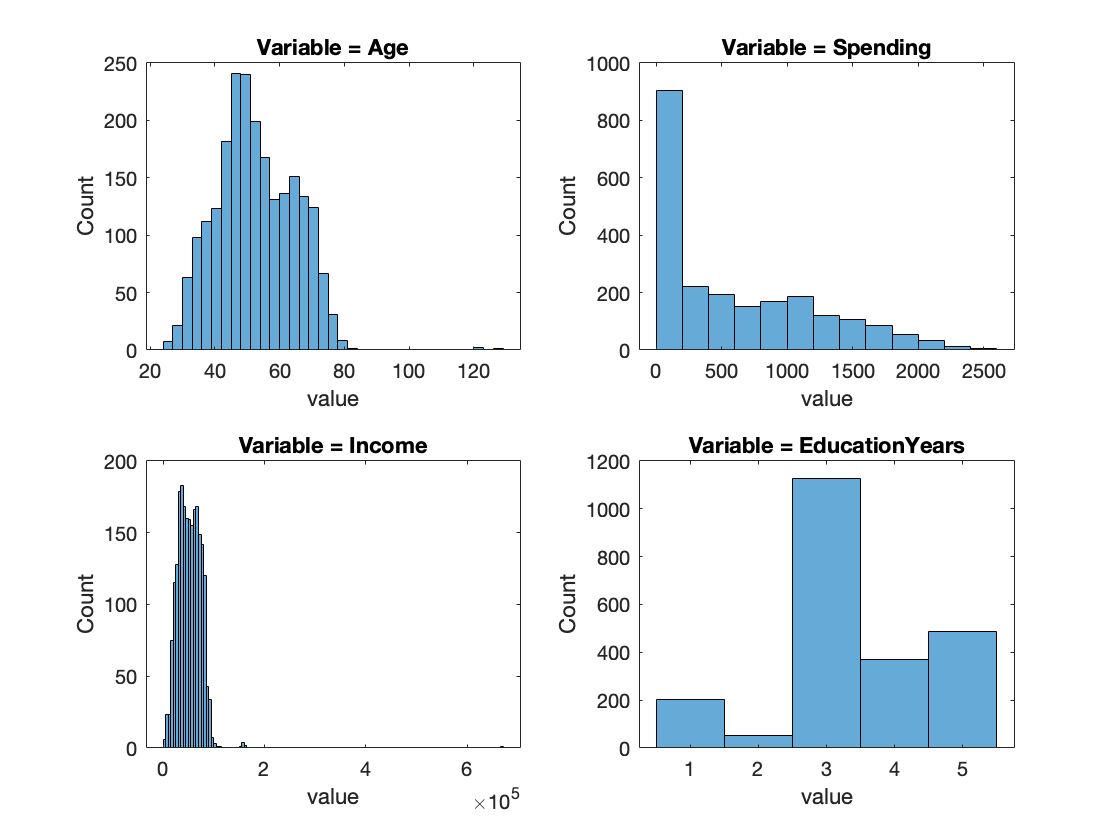

%describe data

% drawing plot
figure
subplot(2,2,1)
histogram(Age)
title('Variable = Age');
xlabel('value');
ylabel('Count');

subplot(2,2,2)
histogram(Spending)
title('Variable = Spending');
xlabel('value');
ylabel('Count');

subplot(2,2,3)
histogram(Income)
title('Variable = Income');
xlabel('value');
ylabel('Count');

subplot(2,2,4)
histogram(Education_years)
title('Variable = EducationYears');
xlabel('value');
ylabel('Count');

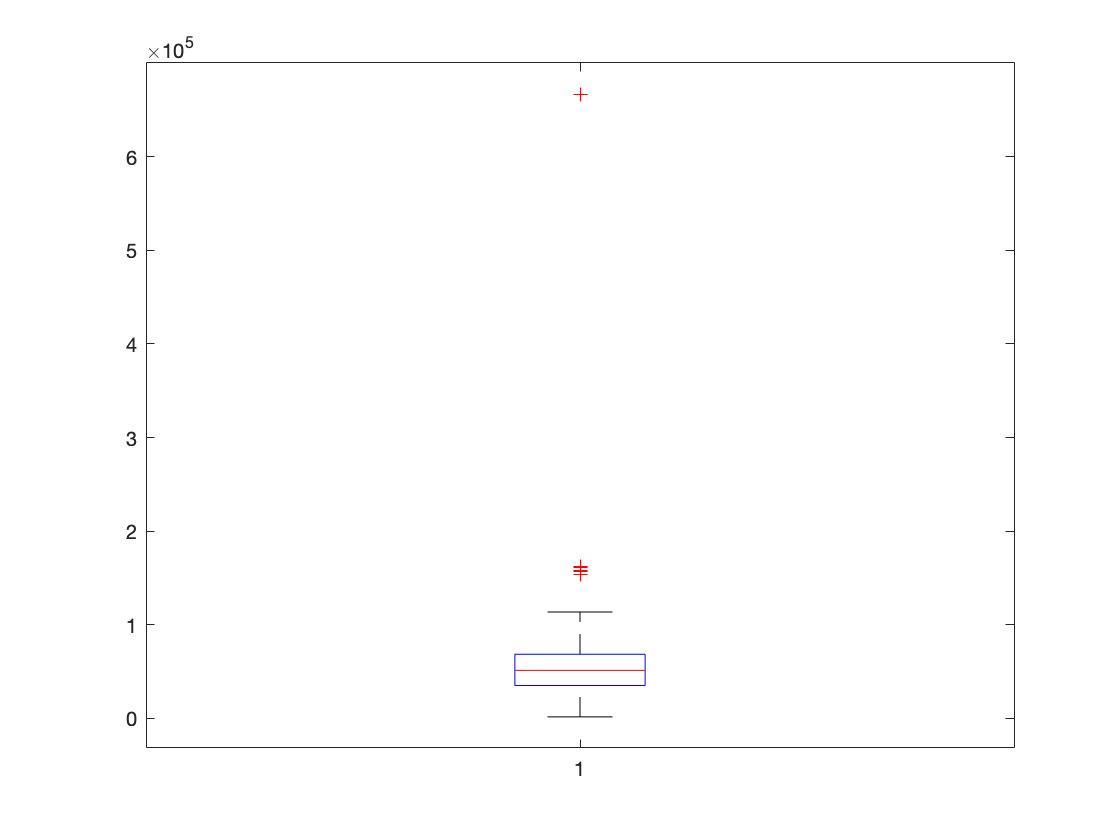

figure
boxplot(Income)

### **Handing outliers**

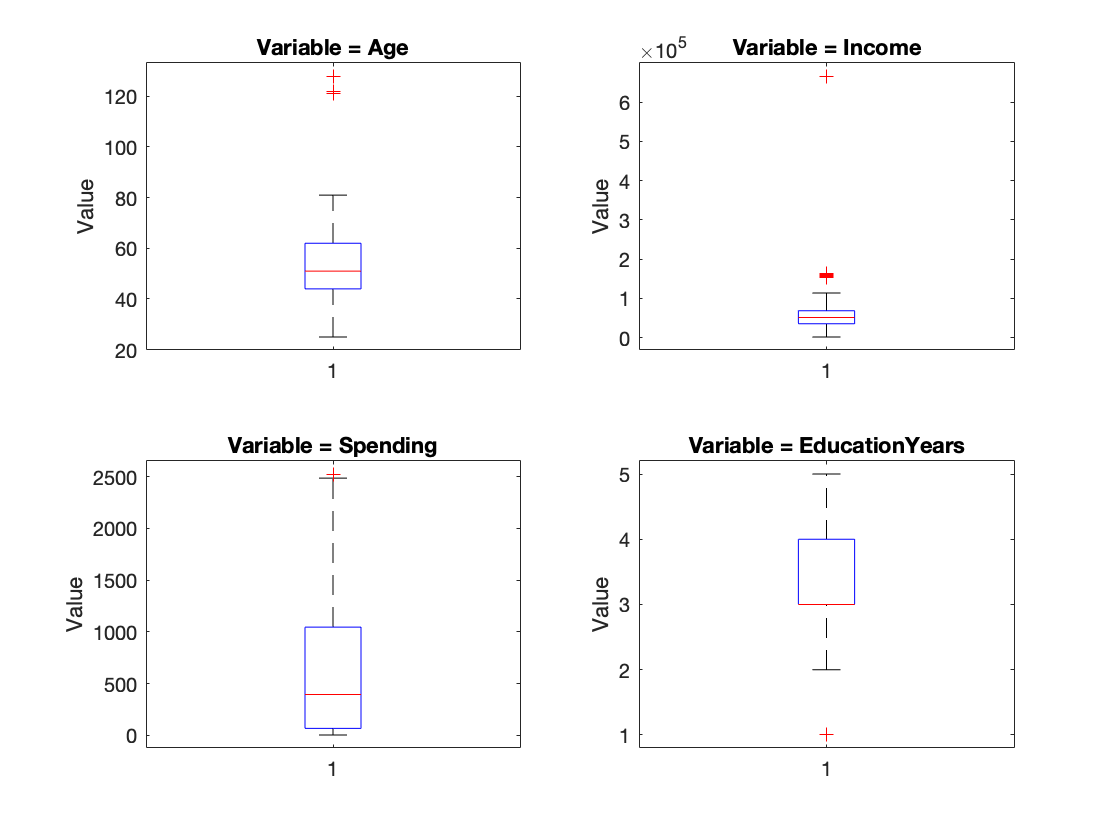

% draw boxplot for Age, Income , Spending, Education_years
figure
subplot(2,2,1)
boxplot(Age)
title('Variable = Age');
ylabel('Value');

subplot(2,2,2)
boxplot(Income)
title('Variable = Income');
ylabel('Value');

subplot(2,2,3)
boxplot(Spending)
title('Variable = Spending');
ylabel('Value');

subplot(2,2,4)
boxplot(Education_years);
title('Variable = EducationYears');
ylabel('Value');

% remove rows which have Income > 600000- it's outliers values
dataset = data(~(data.Income>600000),:);
marketingdata = marketingdata(~(marketingdata.Income>600000),:);
% combine dataset with Education volumn
dataset = join(dataset,table(ID, Education));
disp(dataset);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years    Education 
    _____    ___    __________    ________    _________________    ________    _______________    __________

     1826     51         84835      1190          Alone              No               3           Graduation
        1     60         57091       577          Alone              No               3           Graduation
    10476     63         67267       251          In Couple          Yes              3           Graduation
     1386     54         32474        11          In Couple          Yes              3           Graduation
     5371     32         21474        91          Alone              Yes 

% split data in 7-3, 7(data train), 3(data test)
% cv = cvpartition(size(dataset,1),'HoldOut',0.3);
% datatrain = dataset(cv.training,:);
% datatest = dataset(cv.test,:);

disp(length(dataset.Income));

        2239



### **Handing missing values**

dataset = dataset(~(isnan(dataset.Income)),:);
marketingdata = rmmissing(marketingdata);
disp(dataset);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years    Education 
    _____    ___    __________    ________    _________________    ________    _______________    __________

     1826     51         84835      1190          Alone              No               3           Graduation
        1     60         57091       577          Alone              No               3           Graduation
    10476     63         67267       251          In Couple          Yes              3           Graduation
     1386     54         32474        11          In Couple          Yes              3           Graduation
     5371     32         21474        91          Alone              Yes 

disp(size(dataset));

        2215           8



### Analysis

The total number of enrollment in each year in the following bar graph

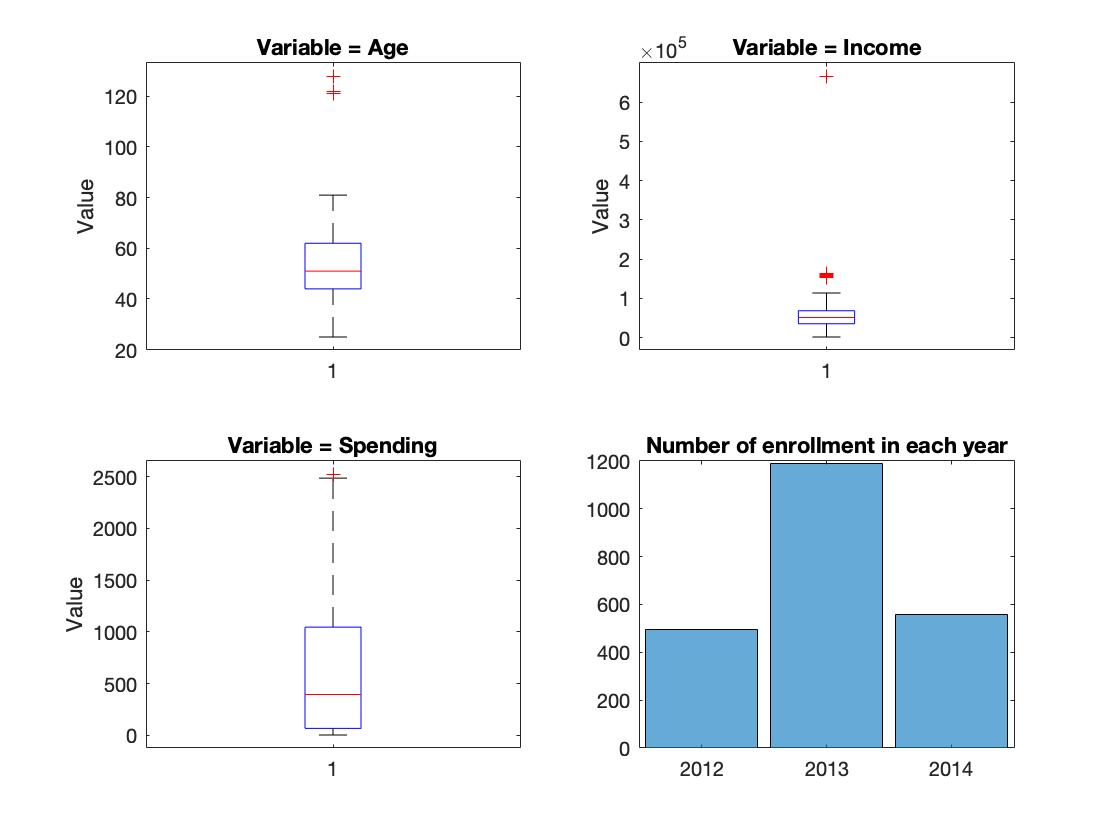

histogram(categorical(year(Dt_Customer)))
title('Number of enrollment in each year');

### Purchases

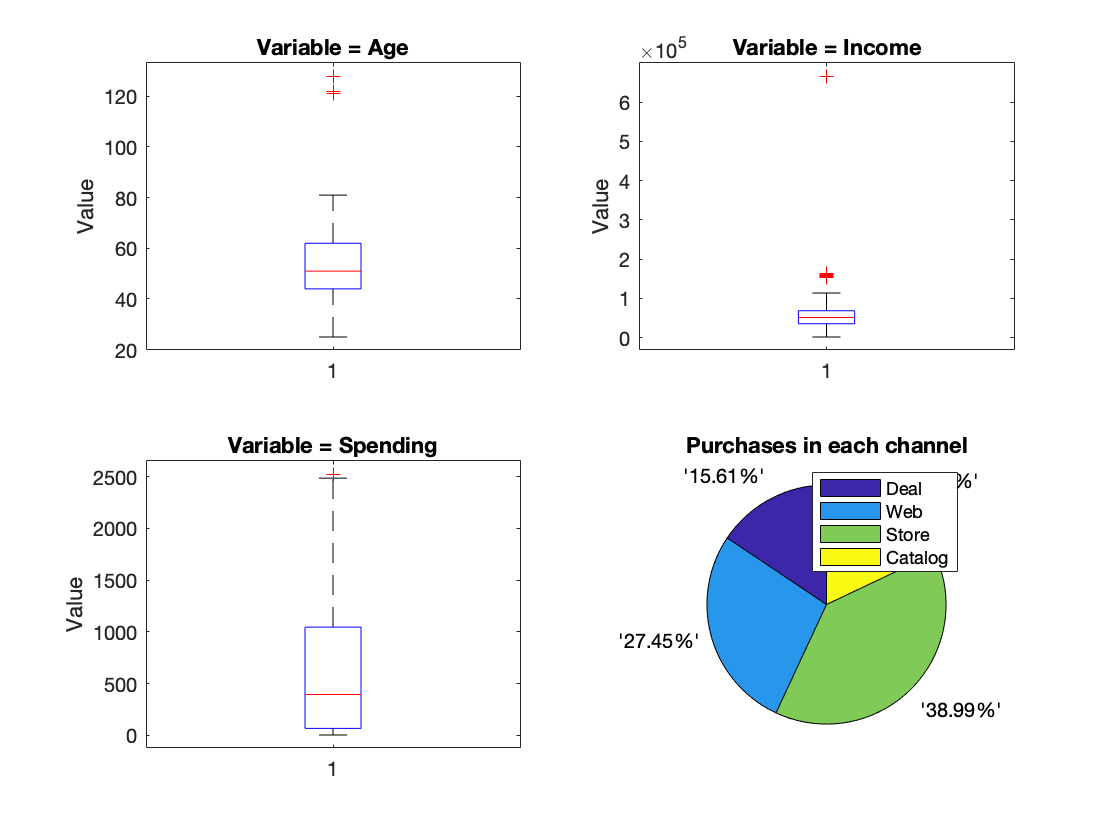

sumDeal = sum(marketingdata.NumDealsPurchases);
sumWeb = sum(marketingdata.NumWebPurchases);
sumStore = sum(marketingdata.NumStorePurchases);
sumCatalog = sum(marketingdata.NumCatalogPurchases);
labels = {'Deal', 'Web','Store','Catalog'};
pie([sumDeal sumWeb sumStore sumCatalog],"'%.2f%%'");
title({'Purchases in each channel'});
% Create legend
legend(labels);

### Products

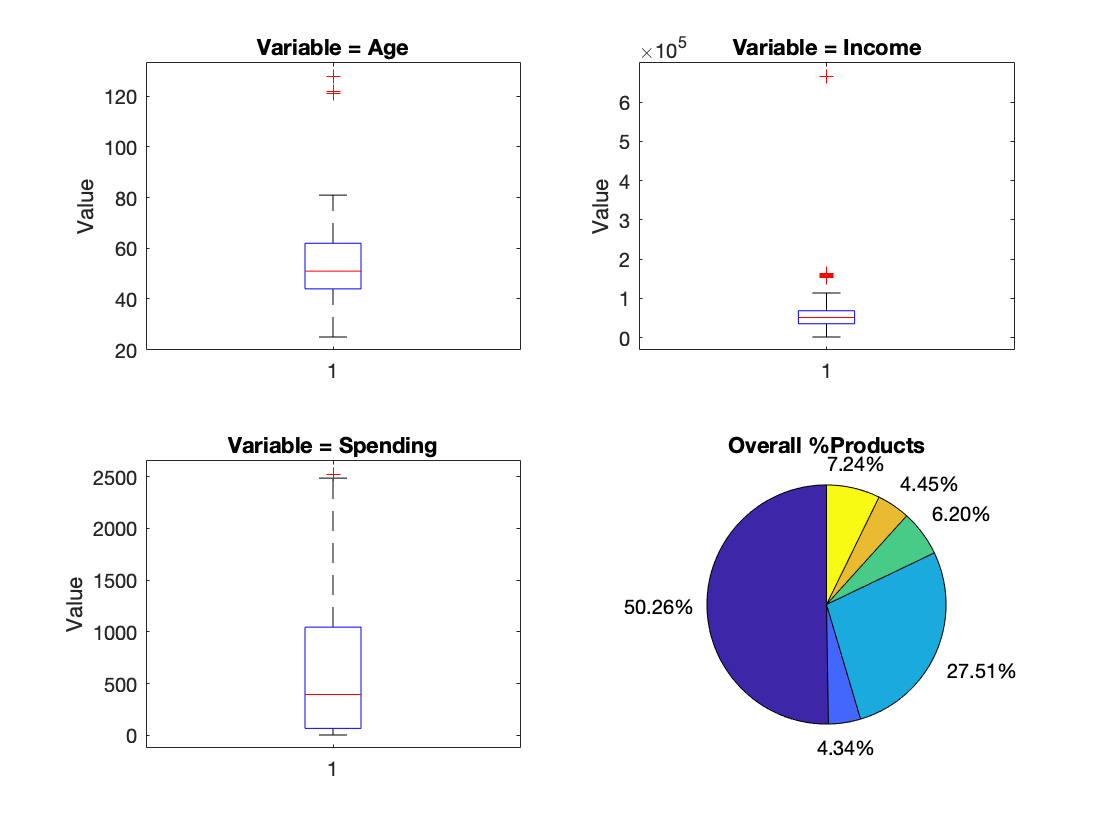

sumWine = sum(marketingdata.MntWines);
sumFruit = sum(marketingdata.MntFruits);
sumMeat = sum(marketingdata.MntMeatProducts);
sumFish = sum(marketingdata.MntFishProducts);
sumSweet = sum(marketingdata.MntSweetProducts);
sumGold = sum(marketingdata.MntGoldProds);
pie([sumWine sumFruit sumMeat sumFish sumSweet sumGold],"%.2f%%");
title({'Overall %Products'});

### Campaign

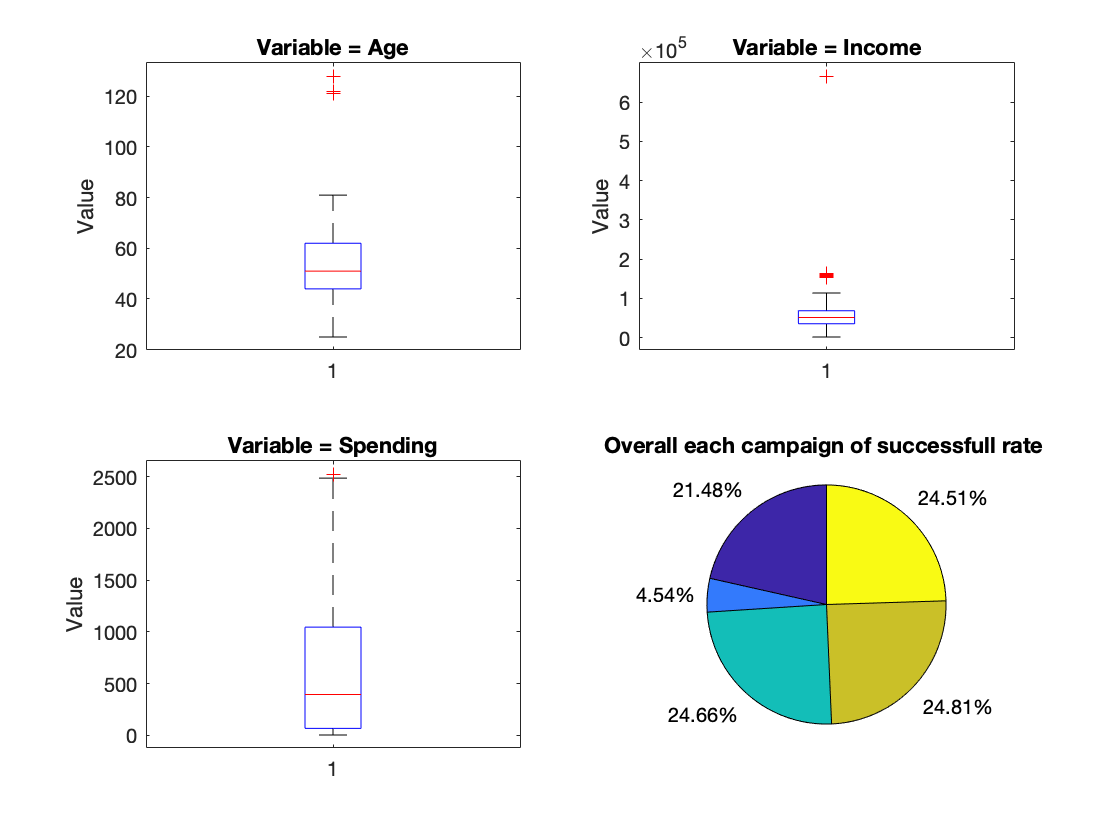

sumCp1 = sum(marketingdata.AcceptedCmp1);
sumCp2 = sum(marketingdata.AcceptedCmp2);
sumCp3 = sum(marketingdata.AcceptedCmp3);
sumCp4 = sum(marketingdata.AcceptedCmp4);
sumCp5 = sum(marketingdata.AcceptedCmp5);
sumcp = [sumCp1 sumCp2 sumCp3 sumCp4 sumCp5];
pie(sumcp,"%.2f%%");
title({'Overall each campaign of successfull rate '});

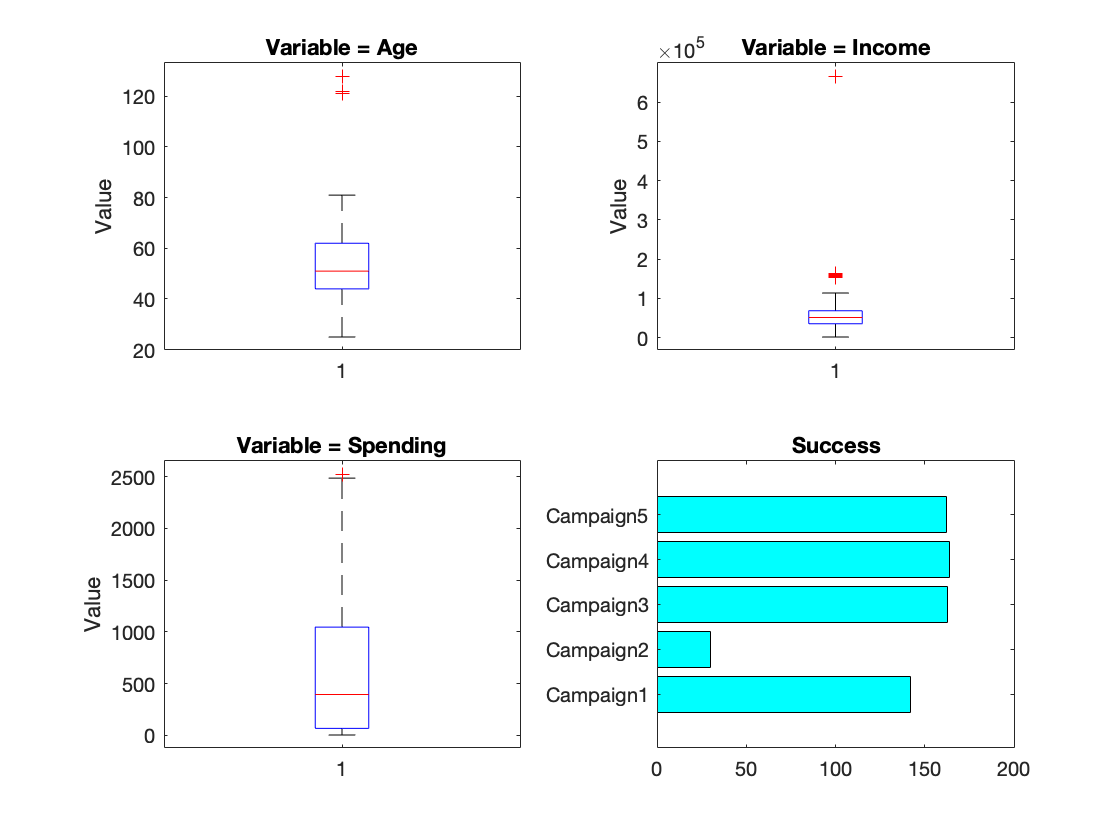

barh(sumcp,'c');
yticklabels({'Campaign1' ,'Campaign2', 'Campaign3' ,'Campaign4',' Campaign5'});
title('Success');

## **VISUAL EXPLORATORY DATA ANALYSIS**

### **Diploma distribution by income level**

nC=0; Bas=0; Gra=0; Mas=0; Ph=0; a1=0; b1=0; c1=0; d1=0; e1=0;
for c=1:length(dataset.Education)
    switch dataset.Education(c)
        case '2n Cycle'
        nC=nC+dataset.Income(c);
        a1=a1+1;
        case 'Basic'
        Bas=Bas+dataset.Income(c);
        b1=b1+1;
        case 'Graduation'
        Gra=Gra+dataset.Income(c);
        c1=c1+1;
        case 'Master'
        Mas=Mas+dataset.Income(c);
        d1=d1+1;
        case 'PhD'
        Ph=Ph+dataset.Income(c);
        e1=e1+1;
    end
end
Y = [nC/a1 Bas/b1 Gra/c1 Mas/d1 Ph/e1];
[y_sorted, y_order] = sort(Y,'ascend');
X = {'2n Cycle' 'Basic' 'Graduation' 'Master' 'PhD'};
x_order=X(y_order);
% X = categorical(x_order);
% X = reordercats(X,x_order);

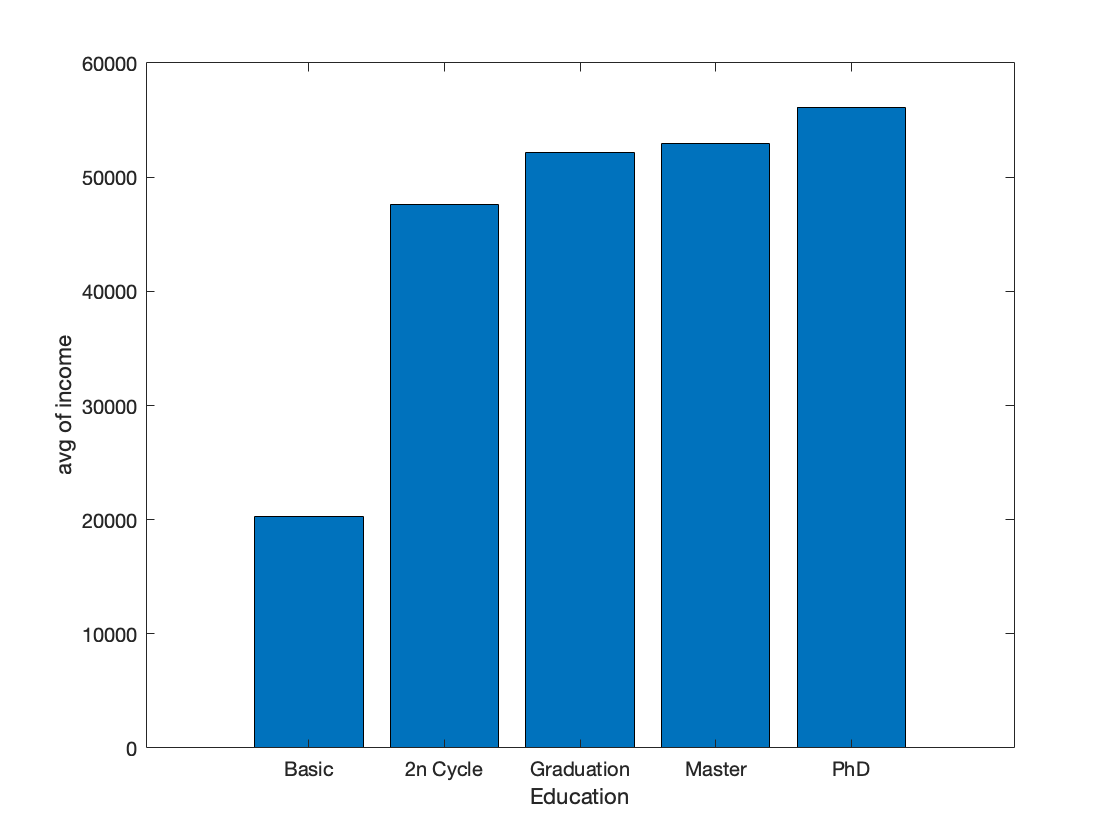

figure
bar(y_sorted);
set(gca,'xticklabel',x_order);
ylabel('avg of income');
xlabel('Education');
set(gca, 'YTickLabel', num2cell(get(gca, 'YTick')))

### **Spending by Income**

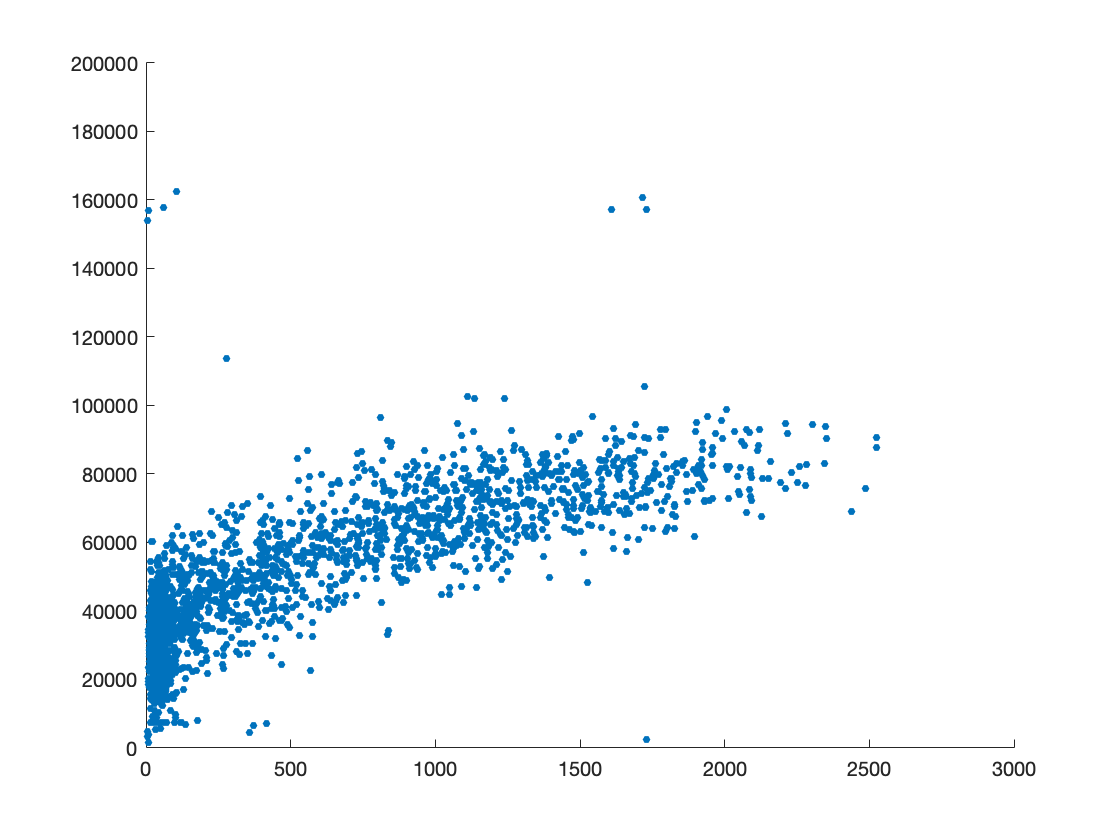

scatter(dataset.Spending,dataset.Income,15,'filled');
ylim([0 200000])
set(gca, 'YTickLabel', num2cell(get(gca, 'YTick')))

### **Diploma distribution by marital situation**

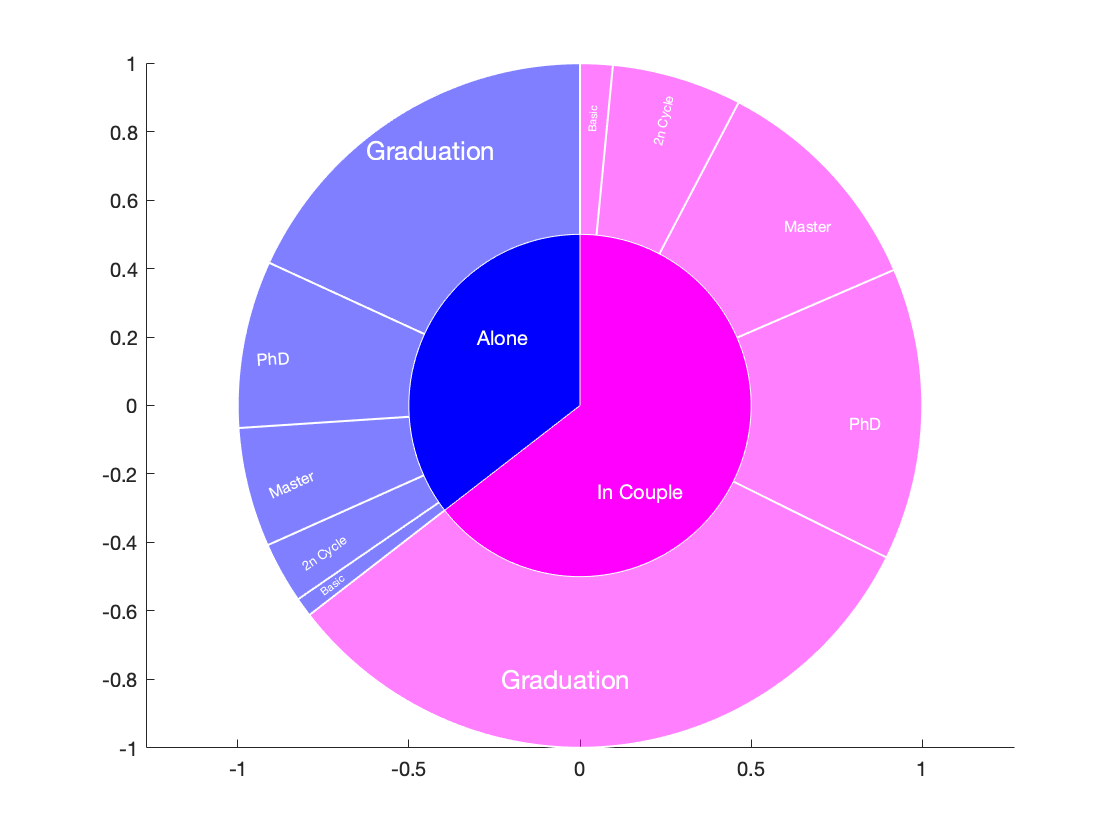

love=zeros(1,length(dataset.Marital_Situation));
X={'2n Cycle','Basic','Graduation','Master','PhD'};
for c=1:length(dataset.Marital_Situation)
    if isequal(dataset.Marital_Situation(c),'In Couple')
        love(c) = 1;
    end
end
nC1 = 0; Bas1 = 0; Gra1 = 0; Mas1 = 0; Ph1 = 0;
nC2 = 0; Bas2 = 0; Gra2 = 0; Mas2 = 0; Ph2 = 0;
for c=1:length(dataset.Education)  
    switch dataset.Education(c)
        case '2n Cycle'
        nC1 = nC1+love(c);
        nC2 = nC2+~love(c);
        case 'Basic'
        Bas1 = Bas1+love(c);
        Bas2 = Bas2+~love(c);
        case 'Graduation'
        Gra1 = Gra1+love(c);
        Gra2 = Gra2+~love(c);
        case 'Master'
        Mas1 = Mas1+love(c);
        Mas2 = Mas2+~love(c);
        case 'PhD'
        Ph1 = Ph1+love(c);
        Ph2 = Ph2+~love(c);
    end
end
couple = [nC1 Bas1 Gra1 Mas1 Ph1];
alone = [nC2 Bas2 Gra2 Mas2 Ph2];
[couple,s1]=sort(couple);
[alone,s2]=sort(alone);
al=sum(alone);
cp=sum(couple);
s=al+cp;
figure
hold on;
axis equal;
t=[0:0.001:1]*2*pi/s;
labels1=X(s1);
labels2=X(s2);
ang1 = t*cp;
ang2 = -t*al;
x1=0.5*sin(ang1);
y1=0.5*cos(ang1);
x2=0.5*sin(ang2);
y2=0.5*cos(ang2);
fill([0 2*x1],[0 2*y1],'m','FaceAlpha', 0.5);
fill([0 2*x2],[0 2*y2],'b','FaceAlpha', 0.5);
cyc = couple'*t;
ap=zeros(1,1001);
for c=1:5   
    h=text(-cyc(c,15)*10+0.5*(sin(ap(1001))+sin(cyc(c,1001)+ap(1001))),0.8*cos(ap(1001)+cyc(c,550)),labels1(c),'Color','w');
    if cyc(c,1001)-cyc(c,1)<pi/6
        set(h,'Rotation',abs(90-90/pi*(ap(1001)+cyc(c,1000))));
    end
    set(h,'fontsize', 5+couple(c)/90);
    ap=ap+cyc(c,:);
    plot([0 sin(ap) 0],[0 cos(ap) 0],'w','LineWidth',1);
    
end
tro = alone'*t;
bp=ap;
for c=1:5
    h=text(0.05+sin(bp(1001)+tro(c,350)),0.05+cos(bp(1001)+tro(c,300)),labels2(c),'Color','w');
    if tro(c,1001)-tro(c,1)<pi/6
        set(h,'Rotation',abs(270-180/pi*(bp(1001))));
    end
    set(h,'fontsize', 5+couple(c)/90);
    bp=bp+tro(c,:);
    plot([0 sin(bp) 0],[0 cos(bp) 0],'w','LineWidth',1);
end

fill([0 x1],[0 y1],'m','EdgeColor','w');
fill([0 x2],[0 y2],'b','EdgeColor','w');
text( 0.05,-0.25,'In Couple','Color','w');
text( -0.3,0.2,'Alone','Color','w');

### Income level by parental status

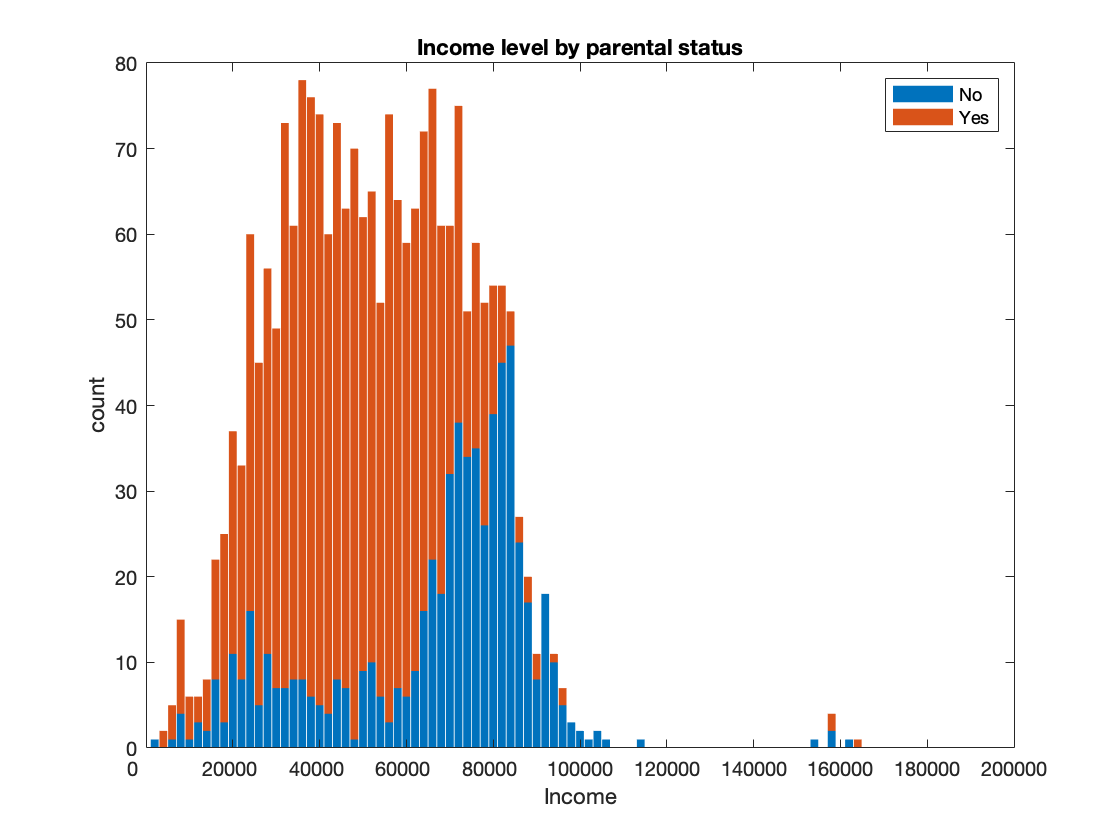

doc legend
Nochild=[];
for c = 1:length(dataset.Income)
    if isequal(dataset.hasChild(c),'No')       
        Nochild = [Nochild ;dataset.Income(c)];
    end
end
edge=0:2000:700000;
edge=[edge inf];
I = histcounts(dataset.Income,edge);
No = histcounts(Nochild,edge);
Yes=I-No;
figure
bar([No(:) Yes(:)],'stacked', 'BarWidth', 0.9);
xlim([0 100])
legend('No','Yes');
xt = get(gca, 'XTick');                                
set(gca, 'XTick', xt, 'XTickLabel', xt*2000);
ylabel('count');
xlabel('Income');
title('Income level by parental status');

## **Kiểm tra tương quan**

**Các biến số: Kiểm tra hệ số tương quan Spearman**

    **Công thức sau được sử dụng để tính toán hệ số tương quan Spearman:**


$$r_s = 1 - \frac{6 \Sigma D^2}{n(n^2 - 1)}$$


$r_s
$ = Hệ số tương quan Spearman

$D
$ = Chênh lệch bậc của các biến tương ứng

$n$ = Số mẫu

Tương quan thứ hạng Spearman là một kiểm tra phi tham số được sử dụng để đo mức độ liên kết giữa hai biến.

Câu hỏi thứ hai là tìm xem liệu có mối tương quan có ý nghĩa thống kê giữa thu nhập và số tiền chi tiêu hay không.

**1. Phát biểu giả thuyết**

* $H_0$: Không có mối liên hệ đơn điệu nào giữa thu nhập và số tiền chi tiêu

* $H_a$: Có sự liên kết đơn điệu giữa thu nhập và số tiền chi tiêu

**2. Lập kế hoạch phân tích**

* ***Mức ý nghĩa***: Kiểm định giả thuyết ở mức ý nghĩa 5%

* ***Phương pháp kiểm tra***: Sử dụng kiểm tra tương quan Spearman để xác định xem hai biến có tương quan hay không. Phương pháp thống kê này định lượng mức độ mà các biến đang xem xét được liên kết bởi một hàm đơn điệu, nghĩa là một mối quan hệ tăng hoặc giảm. Là một kiểm định giả thuyết thống kê, phương pháp này giả định rằng các mẫu không tương quan với nhau (không loại bỏ được $H_0$).

Do đó, nếu giả thiết của chúng ta là đúng, thì kết quả của phép thử sẽ cho phép bác bỏ giả thuyết không.

[RHO,PVAL] = corr(dataset.Spending, dataset.Income,'Type','Spearman');
txt = sprintf('Kiểm tra tương quan Spearman không tham số: Hệ số tương quan: %.4f, p-value: %.4f',[RHO,PVAL]);
disp(txt)

Kiểm tra tương quan Spearman không tham số: Hệ số tương quan: 0.8525, p-value: 0.0000


Rs càng gần +1 hoặc -1, thì mối tương quan có thể càng mạnh. Tương quan dương hoàn hảo là +1 và tương quan âm hoàn hảo là -1. Giá trị $r_s$ là 0,8525 cho thấy một mối quan hệ tích cực khá mạnh.

Hệ số tương quan cao tạo ra mối quan hệ tích cực mạnh mẽ giữa hai biến, xác nhận giả thuyết thay thế.

**Các biến phân loại: Kiểm định Chi bình phương cho tính độc lập**

Câu hỏi thứ ba của chúng tôi là tìm xem liệu có mối tương quan có ý nghĩa thống kê giữa bằng tốt nghiệp và tình hình hôn nhân hay không.

**1. Phát biểu giả thuyết**

* $H_0$ *: Giáo dục và Tình trạng hôn nhân là độc lập

* $H_a$ *: Giáo dục và Tình trạng hôn nhân không độc lập

**2. Lập kế hoạch phân tích**

**** Mức ý nghĩa***: Kiểm tra giả thuyết ở mức ý nghĩa 5%

* ***Phương pháp kiểm tra***: Sử dụng kiểm định Chi bình phương về tính độc lập để xác định liệu có mối quan hệ đáng kể giữa hai biến phân loại hay không.

[table,chi2,p, labels] = crosstab(dataset.Education,dataset.Marital_Situation);
disp(table)

    64   136
    20    34
   402   713
   125   240
   175   306



**Bậc tự do**

Tính toán độ tự do là chìa khóa để hiểu tầm quan trọng của thống kê Chi bình phương và tính hợp lệ của giả thuyết không.

**Bậc tự do được cho bởi công thức:**


$$dof = (r-1)(c-1)$$


Trong đó $r,c
$ lần lượt là số giá trị của $2$ biến phân loại.

[r, c] = size(table);
dof = (r - 1)*(c - 1)

dof = 4

**Thống kê thử nghiệm là một biến ngẫu nhiên Chi bình phương **$(X^2)$** được xác định bởi phương trình sau:**


$$X_c^2 = \Sigma \frac{(O_i - E_i)^2}{E_i}$$


Trong đó:

$O_r$ là tần số đếm được quan sát ở mức $r$ của biến $A$ và mức $c$ của biến $B$

$E_r$ là tần số đếm kì vọng ở mức $r$ của biến $A$ và mức $c$ của biến $B$

significance = 0.05;
critical = chi2inv(1-significance,dof);
fprintf('probability=%.3f, critical=%.3f, stat=%.3f',[1-significance, critical, chi2])

probability=0.950, critical=9.488, stat=1.689

if abs(chi2) >= critical
    fprintf('Dependent (We reject H0)')
else
    fprintf('Independent (We fail to reject H0)')
end

Independent (We fail to reject H0)

**P-value:**

Giá trị P là xác suất quan sát một thống kê mẫu mà cực giống thống kê thử nghiệm. Vì thống kê thử nghiệm là Chi bình phương, chúng ta nên sử dụng bảng Chi bình phương để đánh giá xác suất liên quan đến thống kê thử nghiệm bằng cách sử dụng bậc tự do mà chúng ta đã tìm thấy ở trên.

fprintf('significance=%.3f, p=%.3f',[significance,p]);

significance=0.050, p=0.793

if p <= significance
	fprintf('Dependent (We reject H0)');
else
	fprintf('Independent (We fail to reject H0)');
end

Independent (We fail to reject H0)

**Giải thích kết quả:**

Chúng ta có thể giải thích kết quả theo hai cách:

* P-value cao hơn mức ý nghĩa 5%, chúng ta không bác bỏ giả thuyết vô hiệu.

* Thống kê thử nghiệm thấp hơn giá trị tới hạn, chúng ta không thể bác bỏ giả thuyết không.

Chúng ta có thể kết luận rằng tình trạng hôn nhân độc lập với bằng tốt nghiệp sở hữu ở mức độ tin cậy 95%.